x = linspace(1, 22, 1);
y = sin(x);

N=length(x);
% создаем нулевой массив значений интерполяционного полинома
L=zeros(1, N);
% в цикле считаем сумму по узлам
for k=1:N
    A=1;
    for j=[1:k-1, k+1:N]
        A=conv(A, [1/(x(k)-x(j)), -x(j)/(x(k)-x(j))]);
    end
    L = L + y(k)*A;
end
L

L = -0.0089

L_polyfit = polyfit(x, y, 5)

L_polyfit = 1.0e-08 *

   -0.1717         0         0         0         0         0



% задание точек, в которых требуется найти значения интерполяционного полинома
xx=1:0.5:22;
yy = zeros(1, length(xx));
for i=1:length(xx)
    deg = length(L)-1;
    temp = 0;
    for j=1:length(L)
        temp = temp + L(j)*xx(i)^deg;
        deg = deg - 1;
    end
    yy(1, i) = temp;
end

yy

yy =    -0.0089   -0.0089   -0.0089   -0.0089   -0.0089   -0.0089   -0.0089   -0.0089   -0.0089   -0.0089   -0.0089   -0.0089   -0.0089   -0.0089   -0.0089   -0.0089   -0.0089   -0.0089   -0.0089   -0.0089   -0.0089   -0.0089   -0.0089   -0.0089   -0.0089   -0.0089   -0.0089   -0.0089   -0.0089   -0.0089   -0.0089   -0.0089   -0.0089   -0.0089   -0.0089   -0.0089   -0.0089   -0.0089   -0.0089   -0.0089   -0.0089   -0.0089   -0.0089


polyval(L, xx)

ans =    -0.0089   -0.0089   -0.0089   -0.0089   -0.0089   -0.0089   -0.0089   -0.0089   -0.0089   -0.0089   -0.0089   -0.0089   -0.0089   -0.0089   -0.0089   -0.0089   -0.0089   -0.0089   -0.0089   -0.0089   -0.0089   -0.0089   -0.0089   -0.0089   -0.0089   -0.0089   -0.0089   -0.0089   -0.0089   -0.0089   -0.0089   -0.0089   -0.0089   -0.0089   -0.0089   -0.0089   -0.0089   -0.0089   -0.0089   -0.0089   -0.0089   -0.0089   -0.0089



% построение графиков
plot(x, y, 'o', xx, yy, 'b', xx, sin(xx), 'r'); hold on;
legend('Точки', 'Многочлен Лагранжа', 'sin(x)', 'Location','southwest')
ylim([-2, 2]);
differ = 0;
for i=1:length(yy)
    differ = max(abs(yy(i)-sin(xx(i))), differ);
end
differ

differ = 1.0063



%динамика отклонений
for i=1:length(yy)
    if differ == abs(yy(i)-sin(xx(i)))
        plot([xx(i), xx(i)], [sin(xx(i)), yy(i)], '--');
        break;
    end
end

diff_all = differ;
for m = 1:1:22
    x = linspace(1, 22, m);
    y = sin(x);

    N=length(x);
    % создаем нулевой массив значений интерполяционного полинома
    L=zeros(1, N);
    % в цикле считаем сумму по узлам
    for k=1:N
        A=1;
        for j=[1:k-1, k+1:N]
            A=conv(A, [1/(x(k)-x(j)), -x(j)/(x(k)-x(j))]);
        end
        L = L + y(k)*A;
    end
    
    % задание точек, в которых требуется найти значения интерполяционного полинома
    xx=1:0.5:22;
    yy = zeros(1, length(xx));
    for i=1:length(xx)
        deg = length(L)-1;
        temp = 0;
        for j=1:length(L)
            temp = temp + L(j)*xx(i)^deg;
            deg = deg - 1;
        end
        yy(1, i) = temp;
    end
   
    differ = 0;
    for i=1:length(yy)
        differ = max(abs(yy(i)-sin(xx(i))), differ);
    end
    diff_all = [diff_all, differ];
end

diff_all

diff_all =     1.0063    1.0063    1.6773    1.8941    1.9642    1.9857    2.4927    4.0656    4.2450    6.8624    5.3511    5.1126    3.5918    2.3362    1.4030    0.6938    0.3673    0.1451    0.0696    0.0266    0.1256    0.1536    7.2410


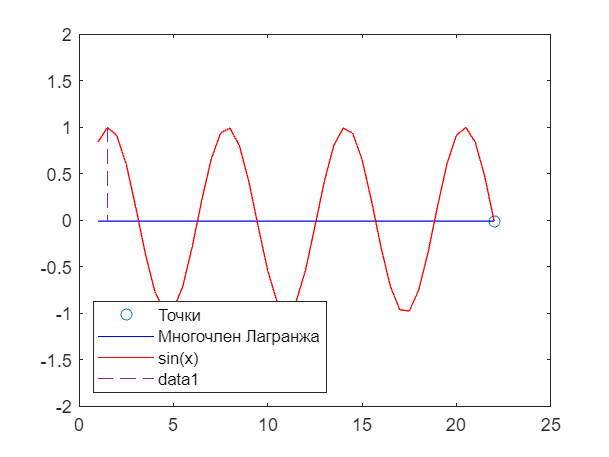

hold off;

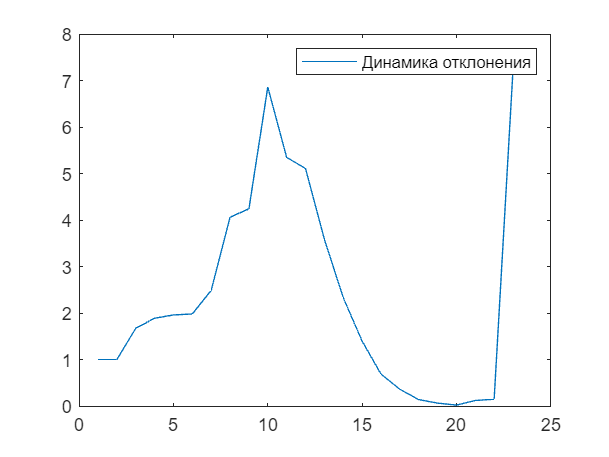

x = 1:length(diff_all);
plot(x, diff_all(x));
legend('Динамика отклонения')